# image input

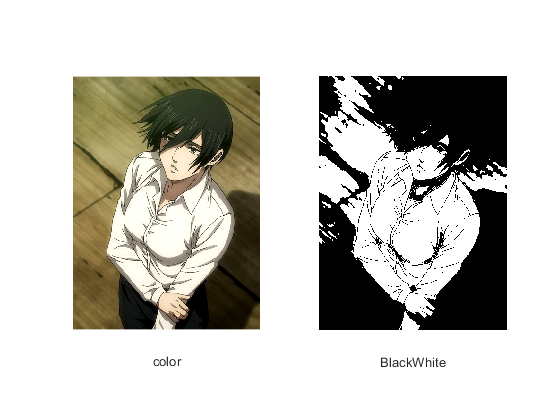

I0 = imread('CV&RSF实验图\实验图\mikasa1.png');
% imshow(I0);

I2 = imresize(I0, 0.5);
% imshow(I2);


Threshold = graythresh(I2);
BW = im2bw(I2, Threshold);
% imshow(BW);

% imwrite(BW,'TRY.jpg');

subplot(1,2,1);imshow(I2);
xlabel('color');


subplot(1,2,2);imshow(BW);
xlabel('BlackWhite')

## hist pixel value

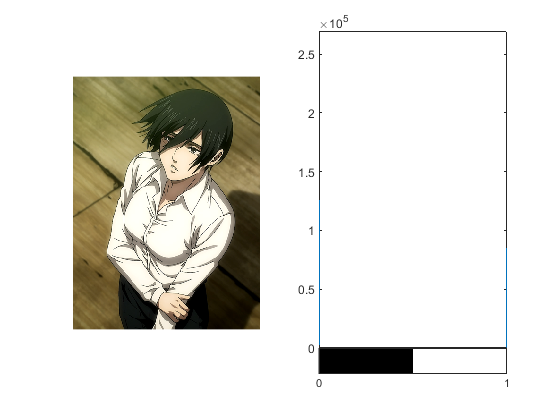

subplot(1,2,1), imshow(BW);
subplot(1,2,2), imhist(BW);


subplot(1,2,1), imshow(I2);

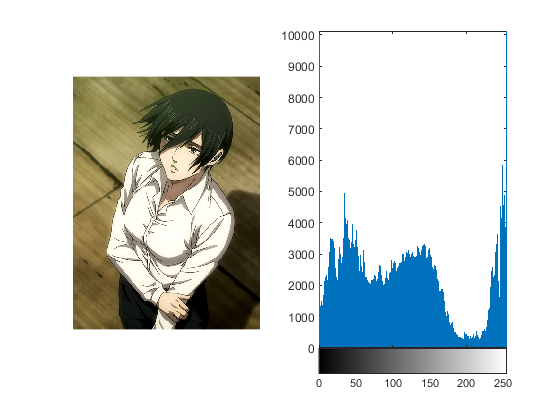

subplot(1,2,2), imhist(I2);

## average image

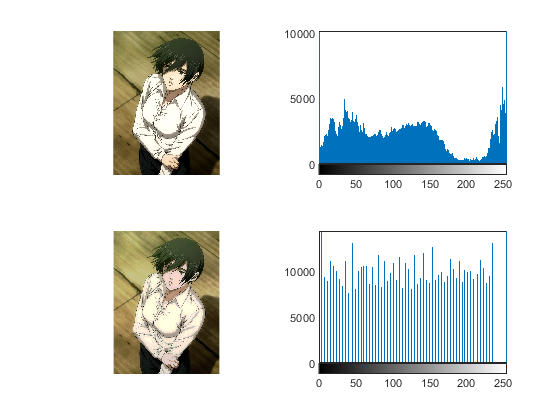

I2_eq = histeq(I2);

% subplot(1,2,1), imshow(I2);
% subplot(1,2,2), imshow(I2_eq);

% 
% subplot(2,1,1), imhist(I2);
% subplot(2,1,2), imhist(I2_eq);

subplot(2,2,1), imshow(I2);
subplot(2,2,2), imhist(I2);
subplot(2,2,3), imshow(I2_eq);
subplot(2,2,4), imhist(I2_eq);

## edge detection1

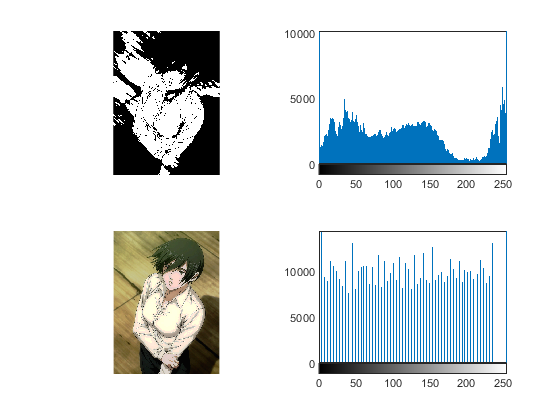

Edge1 = edge(BW,'prewitt');
Edge2 = edge(BW,'log');
Edge3 = edge(BW,'canny');

subplot(2,2,1), imshow(BW);

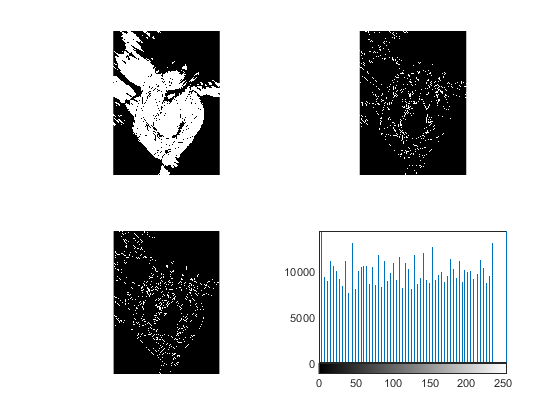

subplot(2,2,2), imshow(Edge1);
subplot(2,2,3), imshow(Edge2);

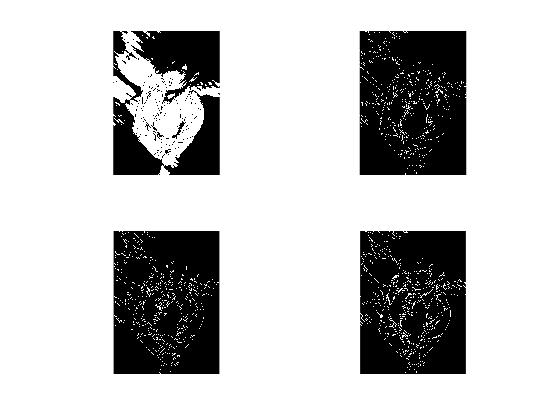

subplot(2,2,4), imshow(Edge3);

## edge detection2

? edge for RGB

using histeq()  first can be helpful!

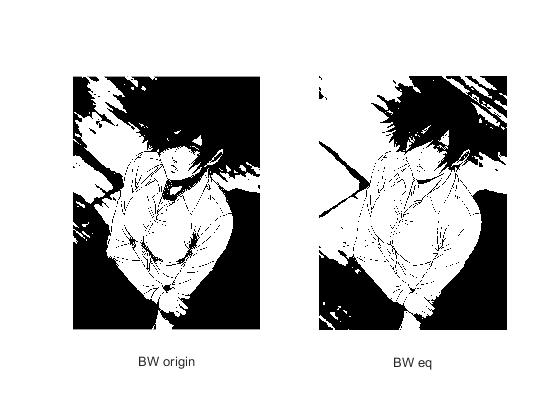

BW_1 = im2bw(I2_eq, graythresh(I2_eq));
% imwrite(BW_1,'TRY.jpg');

subplot(1,2,1), imshow(BW); xlabel('BW origin');
subplot(1,2,2), imshow(BW_1); xlabel('BW eq');


% !! after histeq(), the greysthresh can be more effective!

% Edge3_0 = edge(BW,'canny');
% Edge3_1 = edge(BW_1,'canny');
% subplot(1,2,1), imshow(Edge3_0); xlabel('BW origin edge');
% subplot(1,2,2), imshow(Edge3_1); xlabel('BW eq edge');
% 
